clear;
plotting = 1; % 1 for plot, 0 for no plot

sperate_plotting = 1;

% Base file path
basePath = 'C:\\Users\\xiaom\\Desktop\\LabCourseLab2\\Data\\';

% File name for the d3_3pt data
fileName = '3D_3pt.txt';
filePath = fullfile(basePath, fileName);

% Read the data, skipping the header
data = readmatrix(filePath, 'NumHeaderLines', 22);

% Assign columns to the final variable names using the specified format
d3_3pt.TM = data(:, 2); % Time in seconds
d3_3pt.MF = -data(:, 3) + 75; % MTS Force in N (correction by 80N)
d3_3pt.MD = data(:, 4); % MTS Displacement
d3_3pt.LD = -(data(:, 5) - data(1, 5)); % Laser Displacement, corrected to start from 0

%plot(d3_3pt.MF)
%plot(d3_3pt.LD)

Plotting Load vs Center Deflection

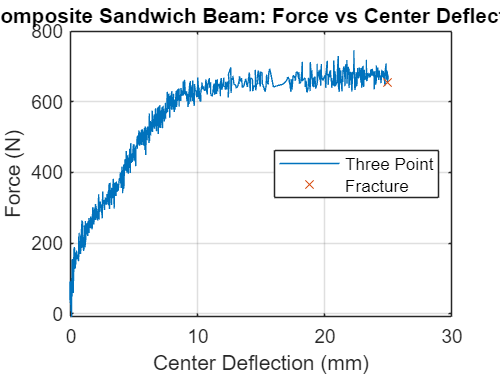

snapind = 995;
truncateind = 995;


d3_3pt.TM = d3_3pt.TM(1:truncateind);
d3_3pt.MF = d3_3pt.MF(1:truncateind);
d3_3pt.MD = d3_3pt.MD(1:truncateind);
d3_3pt.LD = d3_3pt.LD(1:truncateind);

if plotting == 1
    % Plot for Al3: Force vs Laser Displacement
    figure;
    plot(d3_3pt.LD, d3_3pt.MF, 'DisplayName', 'Three Point');
    hold on; % Hold on to add the theoretical line
    plot(d3_3pt.LD(snapind), d3_3pt.MF(snapind), 'X', 'DisplayName', 'Fracture')

    % Add title, labels, and legend
    title('Composite Sandwich Beam: Force vs Center Deflection');
    xlabel('Center Deflection (mm)');
    ylabel('Force (N)');
    legend('show', 'Location', 'best');
    grid on;
    hold off; % Release the plot for other plots
end

Maximum Load and Deflection

D3_MAX_LOAD = mean(d3_3pt.MF(snapind-8:snapind)); % The value is in N
fprintf('D3_MAX_LOAD is %.2f N.\n', D3_MAX_LOAD);

D3_MAX_LOAD is 677.81 N.



D3_MAX_DEFLEC = d3_3pt.LD(snapind); % Snapped at index 238, lost of load force reading
fprintf('D3_MAX_DEFLECTION is %.2f mm.\n', D3_MAX_DEFLEC);

D3_MAX_DEFLECTION is 24.92 mm.
